%question 1
close all;
clear all;
clc
%question 1
H = 3500;%max depth 3500m
zs = 600; %placement of sonar
dt = 0.005;
total_time = 15;
t = 0:dt:total_time;

theta0 = [-2:0.1:2]*pi/180;
len_theta = length(theta0)

len_theta = 41

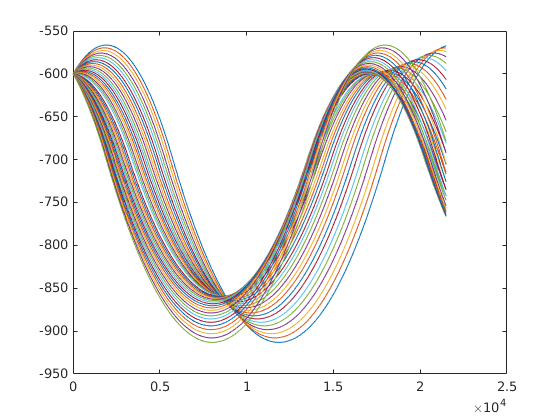

max_depth = 0;
for iii = theta0
    if iii==0
        continue
     
    end
    theta01 = iii;

x1 = zeros(size(t));

z1 = zeros(size(t));

theta1 = zeros(size(t));

c1 = zeros(size(t));


x1(1) = 0;

z1(1) = zs;

theta1(1) = theta01;

c1(1) = velocity(z1(1));

snails_constant1 = cos(theta01)/c1(1);
our_ans = 0;
for i = 1:length(t)
    if i==1
        continue
    end
    
    
    
    x1(i) = x1(i-1) + c1(i-1)*dt*cos(theta1(i-1));
    z1(i) = z1(i-1) + c1(i-1)*dt*sin(theta1(i-1));
    c1(i) = velocity(z1(i));

    %snails_constant1 = cos(theta(i-1))/c(i-1);
    
    if snails_constant1*c1(i) <= 1
        theta1(i) = sign(theta1(i-1))*acos(snails_constant1*c1(i));
    else
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
        
    end
    
    
    if z1(i) < 0
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
    elseif z1(i)>H
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
    end
    
    if max(max(z1))>max_depth
        max_depth = max(max(z1));
    end
    
end


plot(x1,-z1)
hold on
end    
hold off

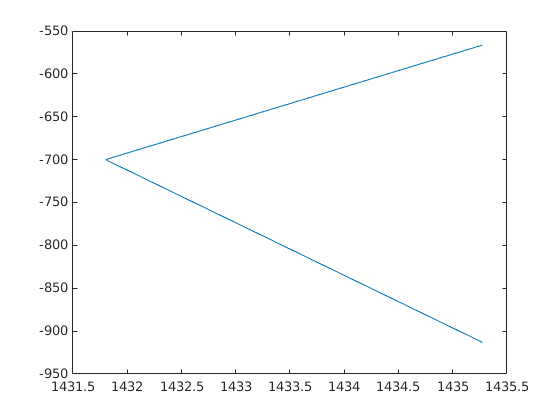

plot(c1,-z1)


ans = sprintf('max_depth: %f', max_depth);
disp(ans)

max_depth: 913.148994


%question 2
%question 1
close all;
clear all;
clc
%question 1
H = 3500;%max depth 3500m
zs = 600; %placement of sonar
dt = 0.0005;
total_time = 15;
t = 0:dt:total_time;


theta01 = 2*pi/180;

x1 = zeros(size(t));

z1 = zeros(size(t));

theta1 = zeros(size(t));

c1 = zeros(size(t));


x1(1) = 0;

z1(1) = zs;

theta1(1) = theta01;

c1(1) = velocity(z1(1));

snails_constant1 = cos(theta01)/c1(1);
our_ans = 0;
for i = 1:length(t)
    if i==1
        continue
    end
    
    
    
    x1(i) = x1(i-1) + c1(i-1)*dt*cos(theta1(i-1));
    z1(i) = z1(i-1) + c1(i-1)*dt*sin(theta1(i-1));
    c1(i) = velocity(z1(i));

    if x1(i)>=10000 
        if (our_ans==0)
        our_ans = sprintf('the distance is %f and the depth is %f',x1(i), z1(i))
        break
        end
    end
    
    
    
    %snails_constant1 = cos(theta(i-1))/c(i-1);
    
    if snails_constant1*c1(i) <= 1
        theta1(i) = sign(theta1(i-1))*acos(snails_constant1*c1(i));
    else
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
        
    end
    
    
    if z1(i) < 0
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
    elseif z1(i)>H
        z1(i) =z1(i-1) ;
        c1(i) = c1(i-2);
        theta1(i) = -theta1(i-2);
    end
    
    
end

our_ans = 'the distance is 10000.414126 and the depth is 891.186619'

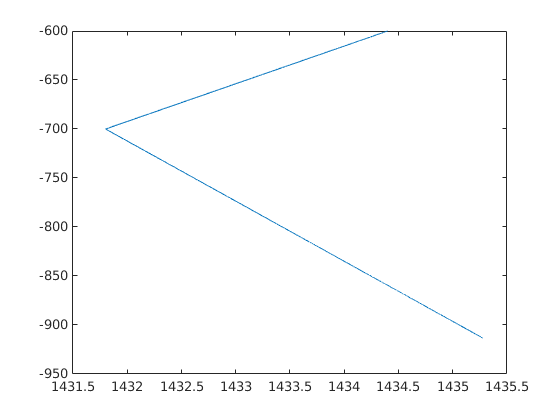



plot(c1(1:i),-z1(1:i))

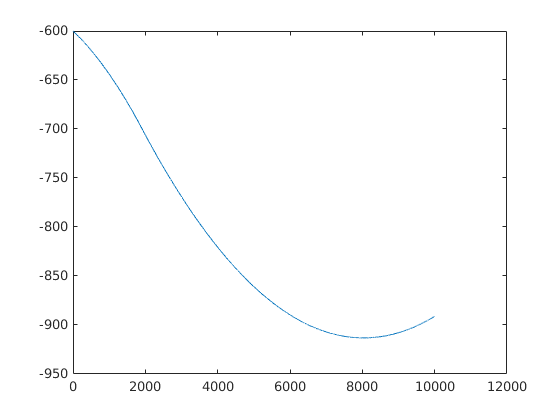


plot(x1(1:i),-z1(1:i))

function c= velocity(z,l,q)
    z2 = 700;
    c0 = 1450;
    
    m1 = -0.026;
    
    c2 = m1*z2 + c0;
    
    if z<z2
        c = m1*z + c0;
    
    elseif z>=z2
        m2 = 1.63*10^-2;
        c = m2*z + (c2 - m2*z2);
    end
    
end